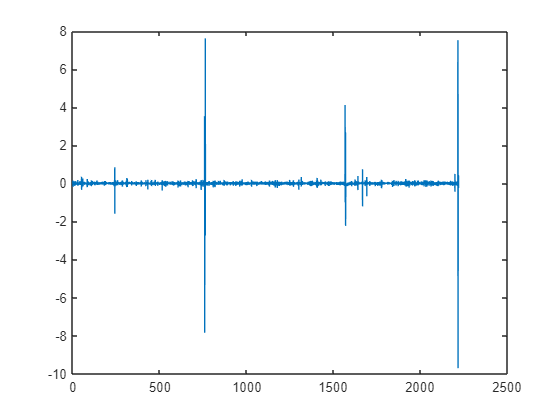

data = csvread('LOL1_37min.csv',5);

time = data(:,2);
y = data(:,4);

figure()
title("Wrist y-accel during a 37 minute game of League of Legends")
plot(time,y)

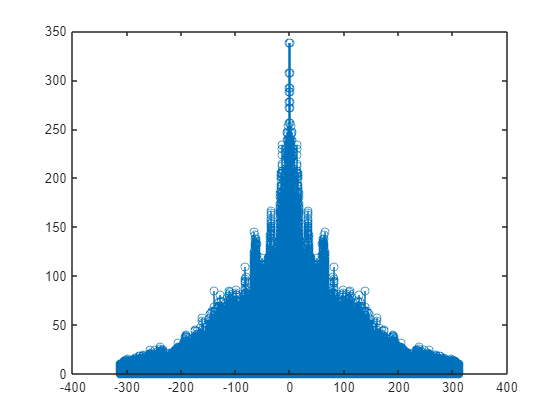

fourier = fftshift(fft(y));

N = 221084;
Fs = 1/(time(2) - time(1));
low = (-pi+(pi/N))*Fs;
high = (pi-(pi/N))*Fs;
frequencies_shifted = linspace(low, high, N)';

figure()
stem(frequencies_shifted,abs(real(fourier)))